clc; clear;

## GLOBAL VARS (TO BE DELETED)

global KTYPE KSCALE p1
global verbose debug

% Set random seed for reproducibility
rng('default');

## Load data

clear; clc; rng(1);

% Parameters for the dataset
n_samples = 3000;  
n_features = 3;   

% Generate random input features
X = rand(n_samples, n_features) * 10 - 5;
x1 = X(:,1);
x2 = X(:,2);

% Define a polynomial relationship for the output (target variable)
Y = 3*x1.^2 + 2*x1.*x2 - 4*x2.^2 + randn(n_samples, 1) * 5;

X_train = X(1:2000,:);
Y_train = Y(1:2000);

X_test = X(2001:end,:);
Y_test = Y(2001:end);

## Parameters

C = 100; % Regularization parameter
epsilon = 0.025; % Insensitivity range

## Kernel definition

ker = 'rbf'; % Kernel type
SIGMA = 1; % Kernel parameter
KTYPE = 6; % Gaussian kernel
KSCALE = (1/(SIGMA*2)^2);
p1 = sqrt(1/(2*KSCALE));

## Level information

verbose = 0;
comparacio = 0;
debug = 0;

## Prepare input

isotropic = 0;
[X, A, B] = svdatanorm(X,ker,isotropic);
X=X(1:end); 
isotropic=1;
MY=max(Y);
mY=min(Y);
Y=Y/(MY-mY);
Y=Y(1:end); 

% Initialize SVM state strcuture
svmState = struct();
svmState.a = [];
svmState.b = 0;
svmState.g = [];
svmState.inds = [];
svmState.indss = [];
svmState.inde = [];
svmState.indes = [];
svmState.support = [];
svmState.ing = [];
svmState.ings = [];
svmState.indo = [];
svmState.R = [];
svmState.Qs = [];
svmState.Qc = [];
svmState.processed = [];
svmState.eps = [];
svmState.eps2 = [];
svmState.tol = [];

## Incremental addition of points

trnX = X;
trnY = Y;
tstX = [];
tstY = [];

% Incremental addition of points
fprintf('\n ** Incremental addition of %g points **\n\n',length(trnX));


 ** Incremental addition of 9000 points **



st = cputime;
% Training svr with first data.
trnX1 = trnX(1);
trnY1 = trnY(1);
svmState = svrm_train(trnX1, trnY1, C, epsilon);

Support vector soft-margin regression with incremental learning
  1 training points
  1 dimensions



% Starting incremental learning
for trnexmp=2:length(trnX)
  new_trnX=trnX(trnexmp); 
  new_trnY=trnY(trnexmp);
  [svmState, error] = svrm_train_afegir(svmState, trnX1, trnY1, new_trnX, new_trnY, C, epsilon);
  trnX1=[trnX1; new_trnX]; trnY1=[trnY1; new_trnY];
  figure(1);
  warning off
  % svrplot(trnX1,trnY1,ker,svmState.a,svmState.b,epsilon,0.0001,1,A,B,mY,MY);
  warning on
  M(trnexmp-1) = getframe;
end
fprintf('Execution time : %4.1f seconds\n',cputime - st)
figure(1);
% svrplot(trnX1,trnY1,ker,svmState.a,svmState.b,epsilon,0.0001,1,A,B,mY,MY);

ls=length(svmState.inds)+length(svmState.indss);
le=length(svmState.inde)+length(svmState.indes);
[Lx,tx]=size(X);
fprintf('\nSupport vectors : %g (%4.1f)', ls, ls*100/Lx);
fprintf('\nError vectors   : %g (%4.1f)\n\n', le, le*100/Lx);

if comparacio==1
%  a' 
%  b
%  g'
%  ((2*epsilon)-g)'
  n = size(trnX,1);m = size(trnX,1);H = zeros(m,n);  
  for i=1:m
    for j=1:n
      H(i,j) = svkernel(ker,trnY(i,:),trnY(j,:));
    end
  end

  W = -max(a,zeros(length(a),1))'* H *min(a,zeros(length(a),1)) - trnY'*a + epsilon*sum(abs(a)); 
  fprintf('Energy=%g \nSum alpha=%g\n\n', W,sum(a))
end 

## Example of Y variation

l1=round(length(trnX)/4);
indmod=randperm(length(trnX));indmod=indmod(1:l1);
trnX3= trnX(indmod);  trnY3= trnY(indmod)+(rand(l1,1)/4)-0.12;
trnX1=trnX3(1); trnY1=trnY3(1);
fprintf('\n  ** Variation in target values of %g points ** \n\n',length(trnX3));


  ** Variation in target values of 15 points ** 



st = cputime;
for trnexmp=2:length(trnX3),
    trnX2=trnX3(trnexmp); trnY2=trnY3(trnexmp);
    [svmState, error] = svrm_train_treure(svmState, trnX, trnY, trnX2, trnY2, C, epsilon);
	indX=find(trnX==trnX2);
%    trnY(indX)=trnY2;
	svmState.a=[svmState.a(1:indX-1);svmState.a(indX+1:end)];
	svmState.g=[svmState.g(1:indX-1);svmState.g(indX+1:end)];
	trnX=[trnX(1:indX-1);trnX(indX+1:end)];
	trnY=[trnY(1:indX-1);trnY(indX+1:end)];
	svmState.inds(find(svmState.inds>indX))=svmState.inds(find(svmState.inds>indX))-1;
	svmState.indss(find(svmState.indss>indX))=svmState.indss(find(svmState.indss>indX))-1;
	svmState.indes(find(svmState.indes>indX))=svmState.indes(find(svmState.indes>indX))-1;
	svmState.inde(find(svmState.inde>indX))=svmState.inde(find(svmState.inde>indX))-1;
	svmState.indo(find(svmState.indo>indX))=svmState.indo(find(svmState.indo>indX))-1;
	svmState.support(find(svmState.support>indX))=svmState.support(find(svmState.support>indX))-1;
	svmState.Qs=[svmState.Qs(:,1:indX-1) svmState.Qs(:,indX+1:end)];

    [svmState, error] = svrm_train_afegir(svmState, trnX, trnY, trnX2, trnY2, C, epsilon);
    trnX=[trnX; trnX2]; trnY=[trnY; trnY2];
%	figure(3);
%	svrplot(trnX,trnY,ker,a,b,epsilon,mag,xaxis,A,B,mY,MY);
%   M(trnexmp-1) = getframe;
%    input('');
end
fprintf('Execution time : %4.1f seconds\n',cputime - st)

Execution time :  0.2 seconds


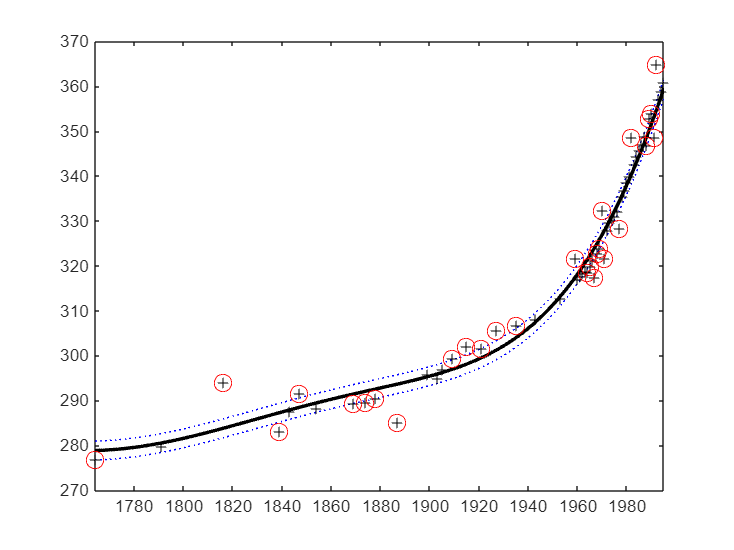

%movie(M,1,2);
%warning off
%movie2avi(M,'vari.avi','FPS',2,'QUALITY',100,'COMPRESSION','Indeo5');
%warning on
%end

%svrplot([trnX; tstX],[trnY; tstY],ker,a,b,epsilon,mag,xaxis,A,B,mY,MY);
figure(2);
svrplot(trnX,trnY,ker,svmState.a,svmState.b,epsilon,0.0001,1,A,B,mY,MY);


ls=length(svmState.inds)+length(svmState.indss);
le=length(svmState.inde)+length(svmState.indes);
[Lx,tx]=size(X);
fprintf('\nSupport vectors : %g (%4.1f)', ls, ls*100/Lx);


Support vectors : 4 ( 6.9)

fprintf('\nError vectors   : %g (%4.1f)\n\n', le, le*100/Lx);


Error vectors   : 24 (41.4)



## Comparasion with SVR

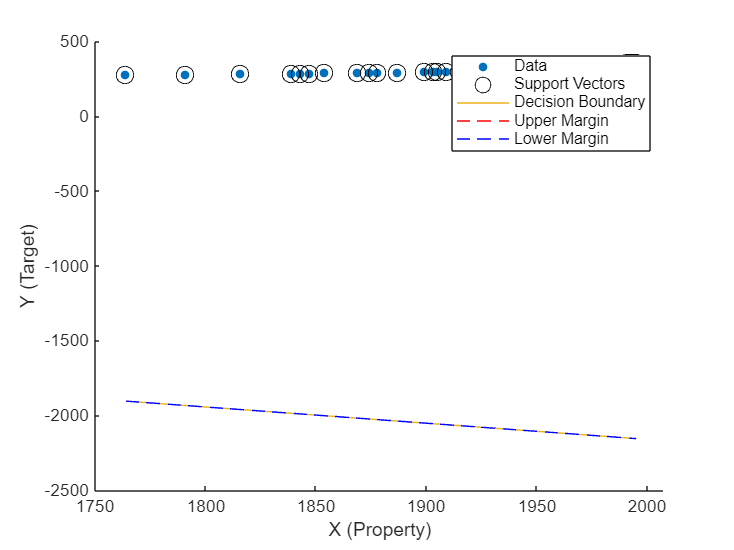


Maximum difference on alphas:  1023.38


Maximum values of alpha     :  38.0967


Relative difference over 1  :  1.02338



Sum of differences          :  3.3335e-06


load carb_dio;
trnX = X;
trnY = Y;
comparacio = 1;
if comparacio
    % Disable warnings temporarily
    warning off  

    % Use MATLAB's built-in SVM regression
    mdl = fitrsvm(trnX, trnY, 'KernelFunction', ker, 'BoxConstraint', C, 'Epsilon', epsilon);

    
    % Extract model parameters
    beta = mdl.Alpha; % Support vector coefficients
    bias = mdl.Bias;  % Model bias
    supportVectors = mdl.SupportVectors;

    % Ensure beta is a column vector
    beta = beta(:);
    trnY = trnY(:);

    m = 1/sqrt(sum(beta(1:end-1).^2)); % Corrected Margin half-width

    % Graficar los datos y el modelo
    figure;
    hold on;
    
    % Assuming trnX is a column vector, otherwise transpose it
    if isrow(trnX)
        trnX = trnX';
    end
    
    % Graficar datos de entrenamiento
    gscatter(trnX, trnY, [], [], [], [], 'off');

    % Extraer indices de los vectores soporte
    supportVectorIndices = find(mdl.IsSupportVector);
    
    % Graficar vectores de soporte
    plot(trnX(supportVectorIndices), trnY(supportVectorIndices), 'ko', 'MarkerSize', 10);
    legend('versicolor','virginica','Support Vector');
    
    % Crear puntos para la línea de decisión
    X1 = linspace(min(trnX), max(trnX), 100);
    
    % Compute Y1 based on the decision boundary formula: Y = (-bias - X*beta(1)) / beta(2)
    Y1 = -(bias + X1 * beta(1)) / beta(2);
    
    % Graficar la línea de decisión y los márgenes
    plot(X1, Y1, '-'); % Línea de decisión
    plot(X1, Y1 + m, 'r--'); % Margen superior
    plot(X1, Y1 - m, 'b--'); % Margen inferior
    
    xlabel('X (Property)');
    ylabel('Y (Target)');
    legend('Data', 'Support Vectors', 'Decision Boundary', 'Upper Margin', 'Lower Margin');
    hold off;

    % Plot the model using MATLAB's built-in SVM parameters
    %figure(3);
    %svrplot(trnX, trnY, ker, beta, bias, epsilon, 0.0001, 1, A, B, mY, MY);

    % Calculate and display differences between custom and built-in model
    fprintf('\nMaximum difference on alphas:  %g', max(abs(svmState.a - beta)));
    fprintf('\nMaximum values of alpha     :  %g', max(abs(beta)));
    fprintf('\nRelative difference over 1  :  %g\n', max(abs(svmState.a - beta)) / max(abs(svmState.a)));
    fprintf('\nSum of differences          :  %g\n', sum(svmState.a - beta));

    warning on
end